# MECH 6323 - Homework 4

Author: Jonas Wanger

Date: 2022-03-13

clear
close all

## Problem 1

### Part a

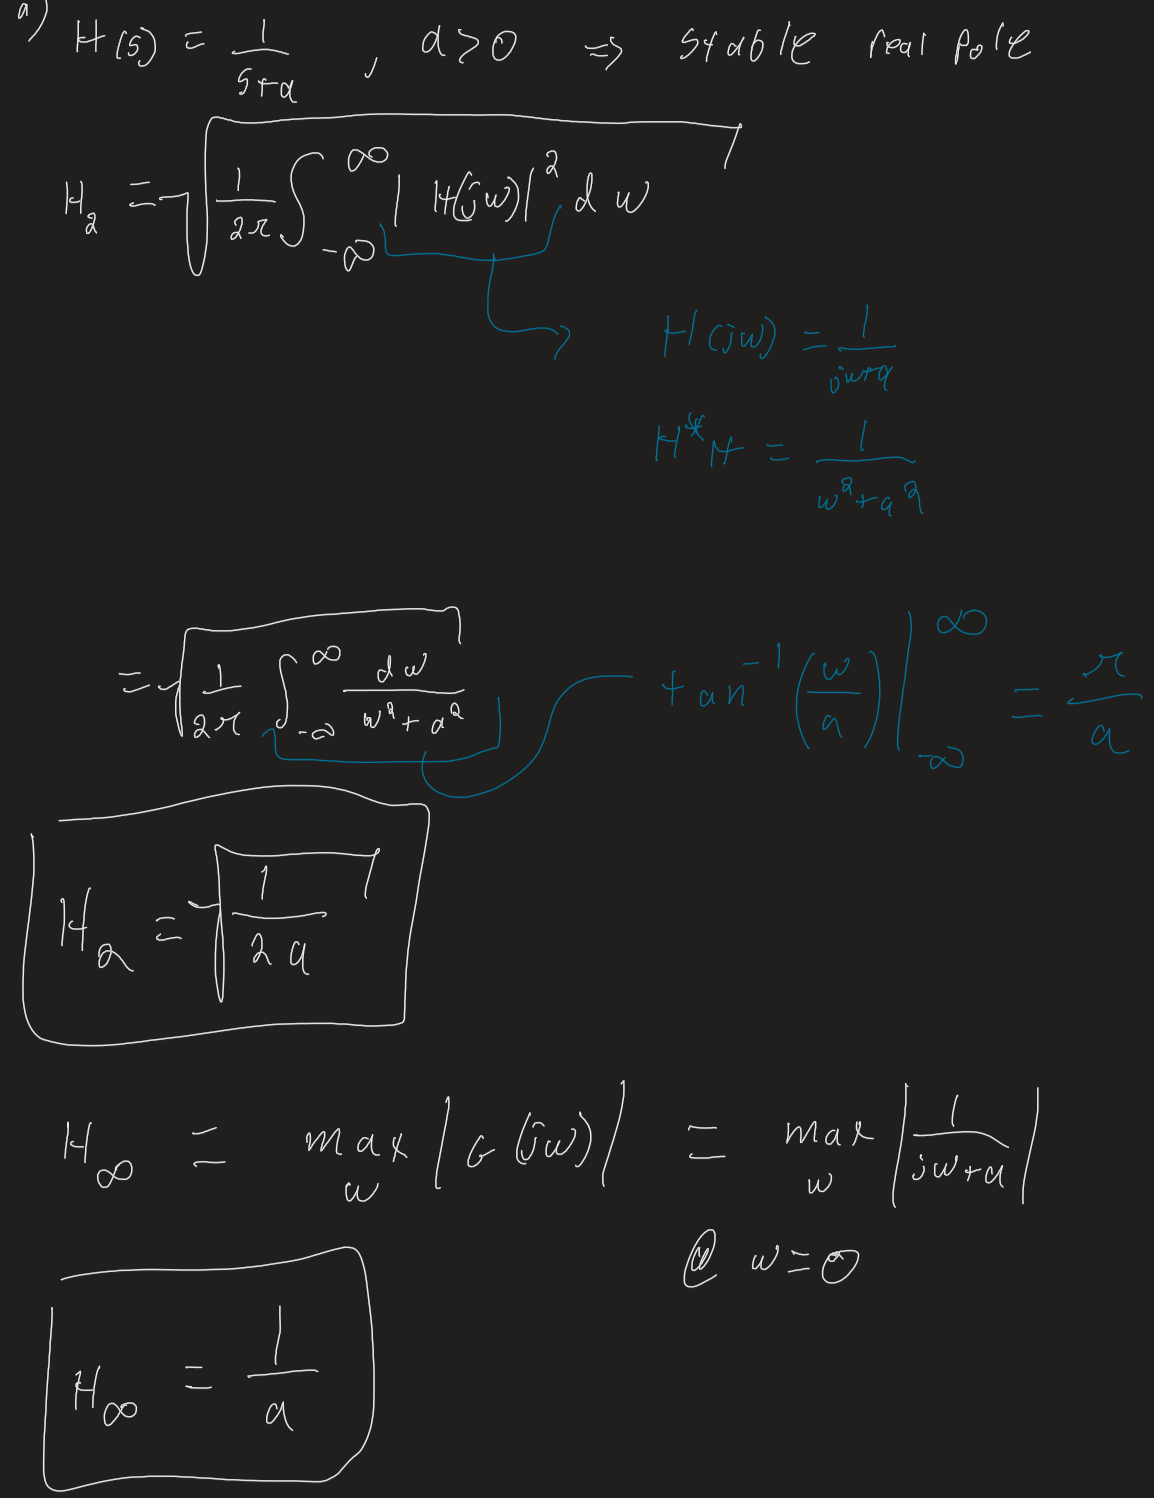

### Part b

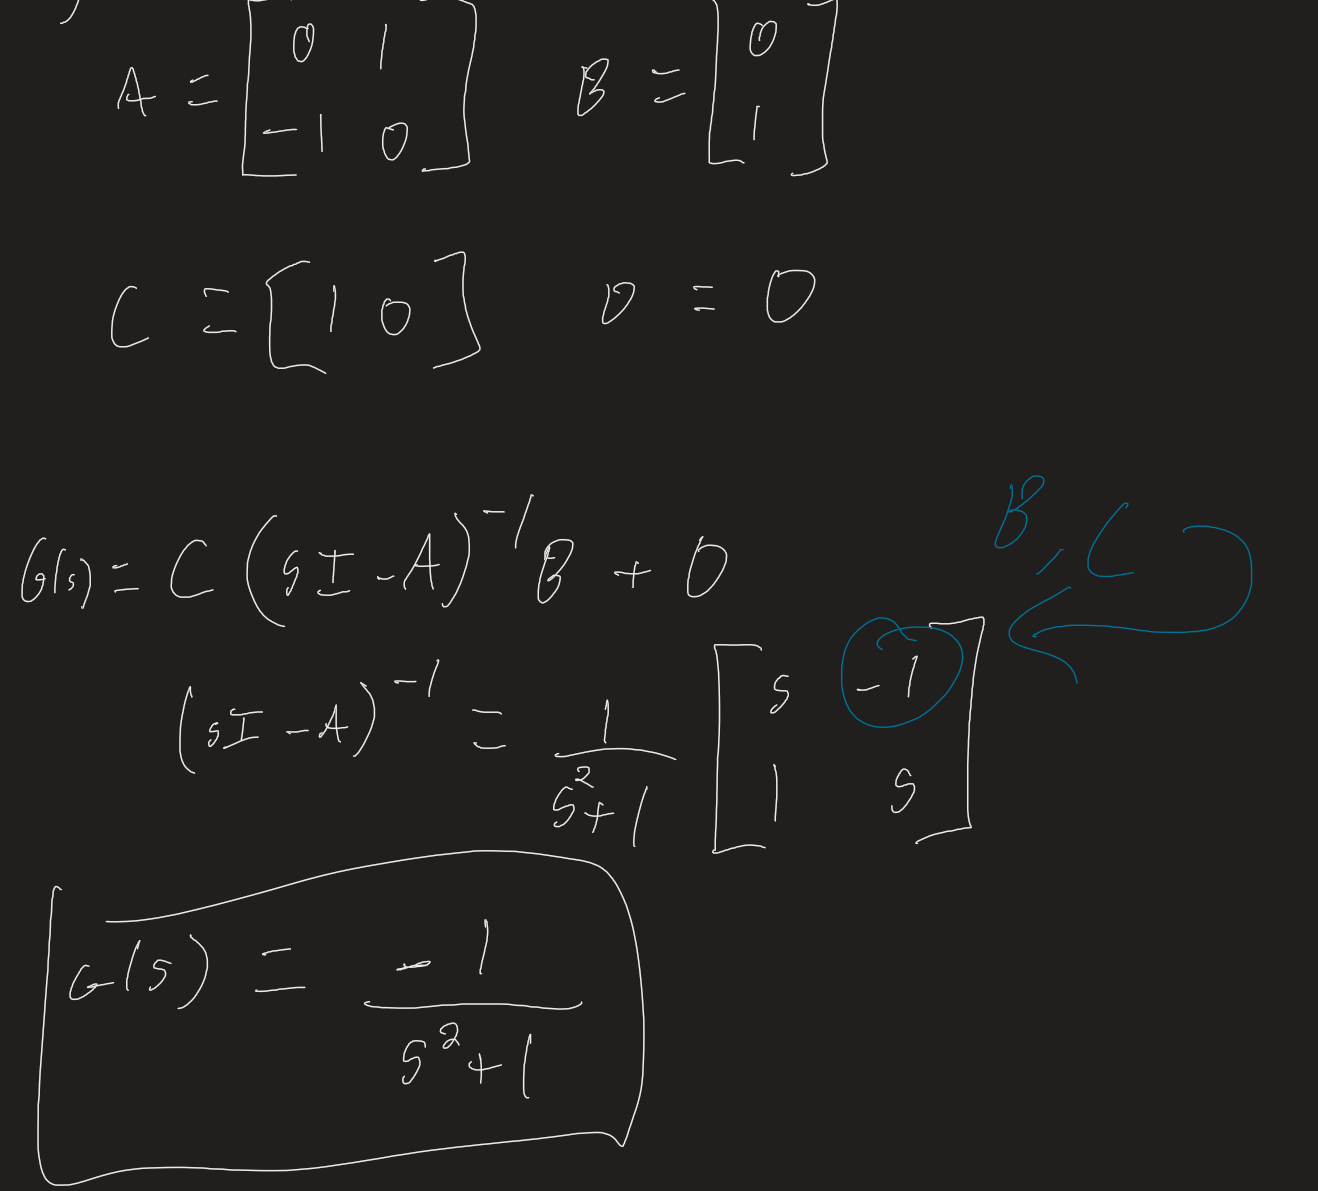

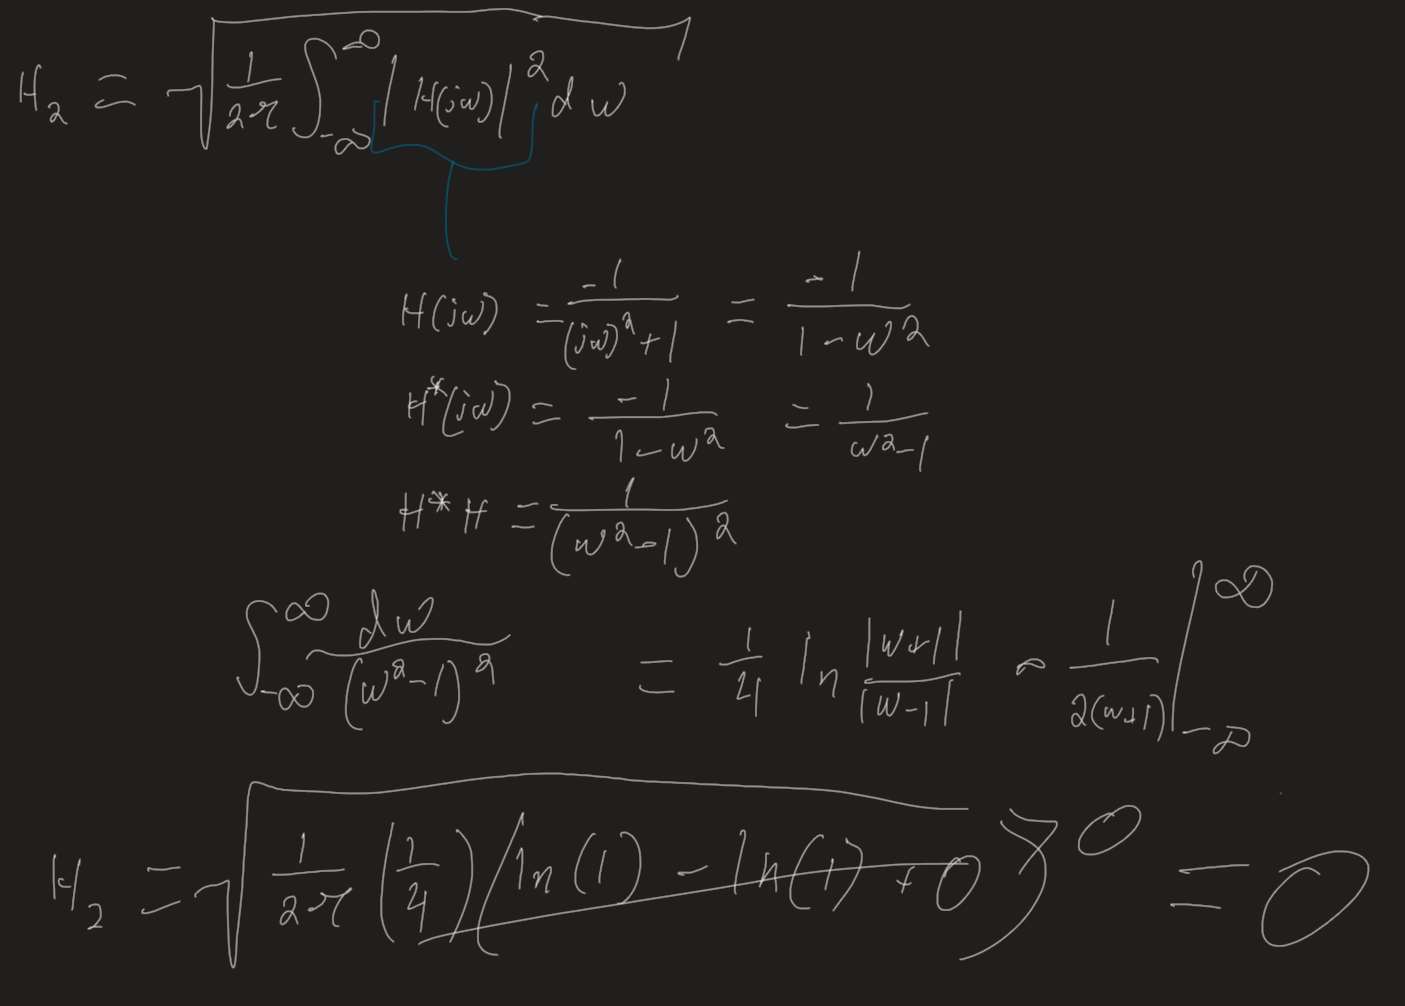

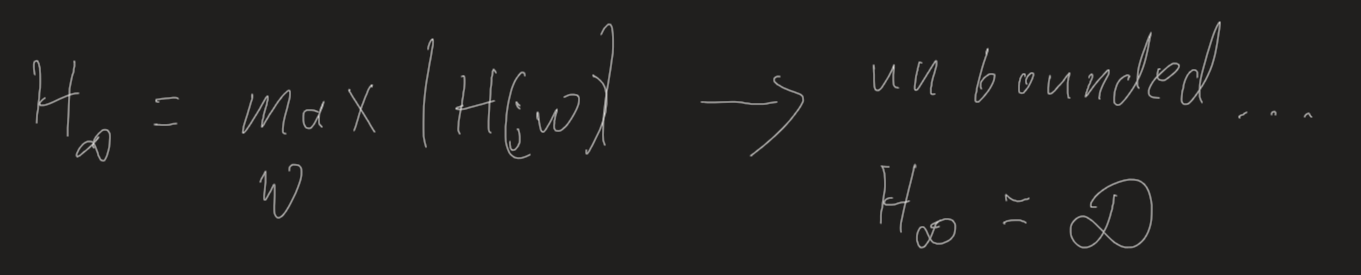

## Problem 2

### Part a

% simple written down already
k = sym('k', 'real');
R = sym('R', 'real'); % should be positive... will show

A = [
    -(1 + k^2)/R    0
    k               -(2+k^2)/R]

$$A = \left(\begin{array}{cc} -\frac{k^{2}+1}{R} & 0\\ k & -\frac{k^{2}+2}{R} \end{array}\right)$$

Lambda = eig(A)

$$Lambda = \left(\begin{array}{c} -\frac{k^{2}+1}{R}\\ -\frac{k^{2}+2}{R} \end{array}\right)$$

This means that the system is stable $\forall {k \in \mathcal{R}}$ and $\forall {R > 0$

### Part b

R = sym('R', 'positive');
S = svd(A)

$$S = \begin{array}{l} \left(\begin{array}{c} \frac{\sqrt{\sigma_{1}+3\,k^{2}+k^{4}+\frac{R^{2}\,k^{2}}{2}+\frac{5}{2}}}{R}\\ \frac{\sqrt{3\,k^{2}-\sigma_{1}+k^{4}+\frac{R^{2}\,k^{2}}{2}+\frac{5}{2}}}{R} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{\left(R^{2}\,k^{2}+1\right)\,\left(R^{2}\,k^{2}+4\,k^{4}+12\,k^{2}+9\right)}}{2} \end{array}$$

H_2_norm_fun = matlabFunction(norm(S,2), 'Vars', [R, k]);
H_2_norm = H_2_norm_fun(k,R)

$$H\_2\_norm = \begin{array}{l} \sqrt{\frac{\left|3\,R^{2}-\sigma_{1}+R^{4}+\frac{R^{2}\,k^{2}}{2}+\frac{5}{2}\right|}{k^{2}}+\frac{\sigma_{1}+3\,R^{2}+R^{4}+\frac{R^{2}\,k^{2}}{2}+\frac{5}{2}}{k^{2}}}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{\left(R^{2}\,k^{2}+1\right)\,\left(4\,R^{4}+R^{2}\,k^{2}+12\,R^{2}+9\right)}}{2} \end{array}$$

#### Ploting H_2(k,R) vs k

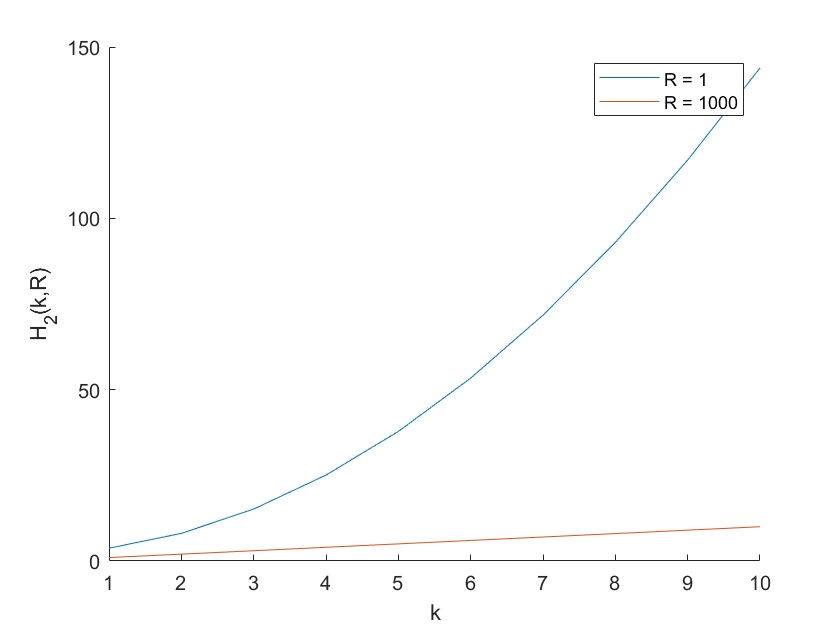

k_val = 1:10;
R_val = [1, 1000];

figure
hold on
for idx = 1:2
    plot(k_val, H_2_norm_fun(R_val(idx), k_val), ...
        'DisplayName', ['R = ', num2str(R_val(idx))]);
end
xlabel('k')
ylabel('H_2(k,R)')
legend

#### Ploting H_2(k,R) vs R

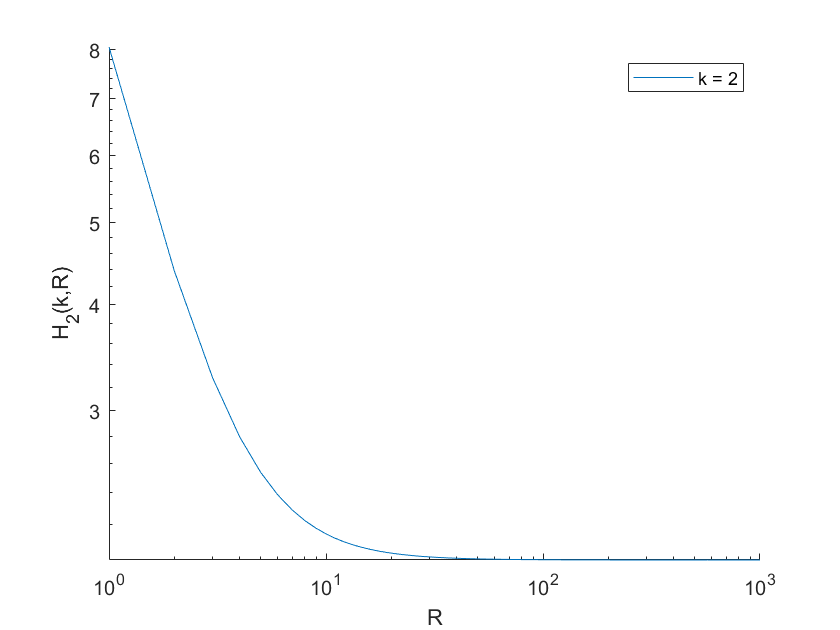

k_val = [2];
R_val = 1:1000;

figure
hold on
for idx = 1:1
    plot(R_val, H_2_norm_fun(R_val, k_val(idx)), ...
        'DisplayName', ['k = ', num2str(k_val(idx))]);
end
xlabel('R')
ylabel('H_2(k,R)')
legend
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')

### Part c

B = [1 0]';
C = [0 1];
D = 0;

G = partfrac(C * inv(sym('s')*eye(2) - A) * B + D, sym('s'), 'FactorMode', 'full')

$$G = \frac{R\,k}{s+\frac{k^{2}+1}{R}}-\frac{R\,k}{s+\frac{k^{2}+2}{R}}$$

Therefore we have:

A_1 = R *k;     lambda_1 = -(k^2 + 1) / R;
A_2 = - R *k;   lambda_2 = -(k^2 + 2) / R;
G_t = A_1 * exp(lambda_1 * sym('t')) + A_2 * exp(lambda_2 * sym('t'))

$$G\_t = R\,k\,{\mathrm{e}}^{-\frac{t\,\left(k^{2}+1\right)}{R}}-R\,k\,{\mathrm{e}}^{-\frac{t\,\left(k^{2}+2\right)}{R}}$$

or directly

G_t = C * expm(A*sym('t')) * B + D

$$G\_t = R\,k\,{\mathrm{e}}^{-\frac{t\,k^{2}+t}{R}}-R\,k\,{\mathrm{e}}^{-\frac{t\,k^{2}+2\,t}{R}}$$

### Part d

sigma_max_fun = matlabFunction(svd(G_t), 'Vars', [R, k, sym('t')]); % SISO system...
sigma_max = sigma_max_fun(R, k, sym('t'))

$$sigma\_max = \sqrt{-\left(R\,k\,{\mathrm{e}}^{-\frac{\bar{t}\,k^{2}+2\,\bar{t}}{R}}-R\,k\,{\mathrm{e}}^{-\frac{\bar{t}\,k^{2}+\bar{t}}{R}}\right)\,\left(R\,k\,{\mathrm{e}}^{-\frac{t\,k^{2}+t}{R}}-R\,k\,{\mathrm{e}}^{-\frac{t\,k^{2}+2\,t}{R}}\right)}$$

**Ploting**

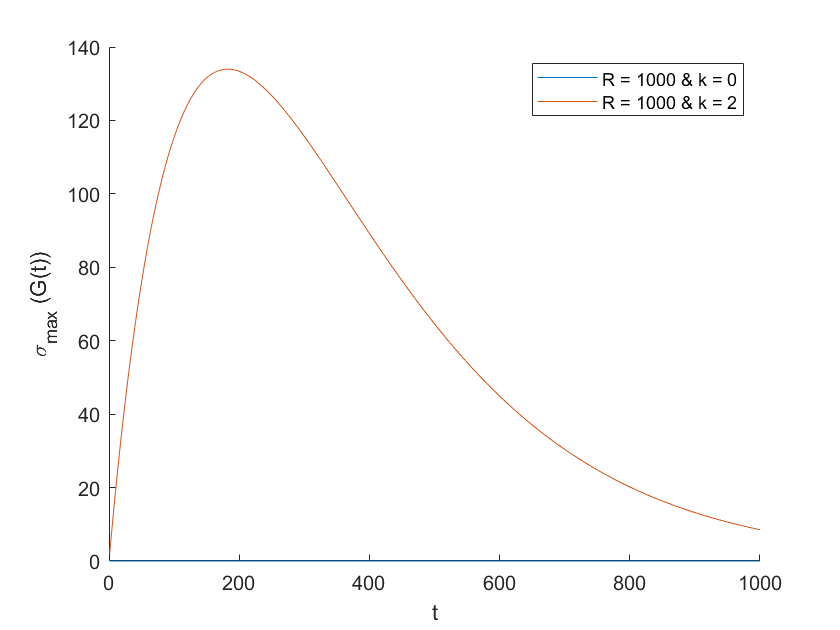

T = 1:1000;
R_val = [1000, 1000];
k_val = [0, 2];

figure
hold on
for idx = 1:2
    plot(T, sigma_max_fun(R_val(idx), k_val(idx), T), ...
        'DisplayName', ['R = ', num2str(R_val(idx)), ' & k = ', num2str(k_val(idx))]);
end

ylabel('\sigma_{max} (G(t))')
xlabel('t')
legend

## Problem 3

### Part a

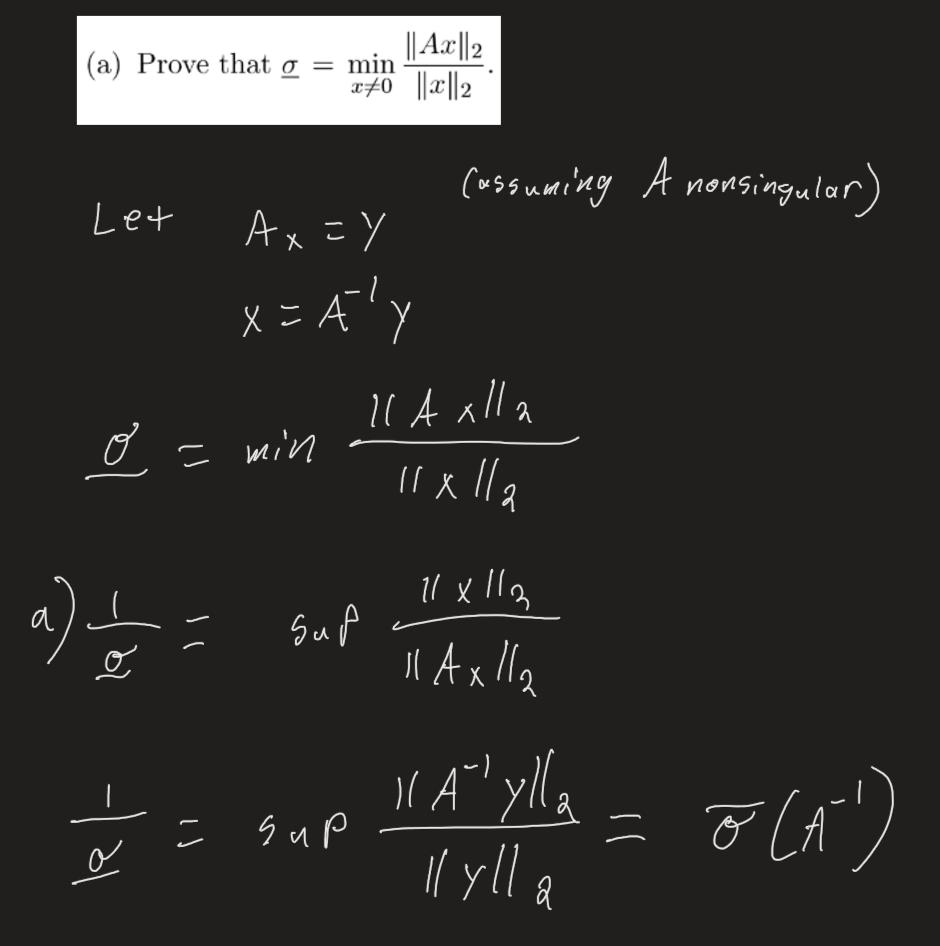

### Part b

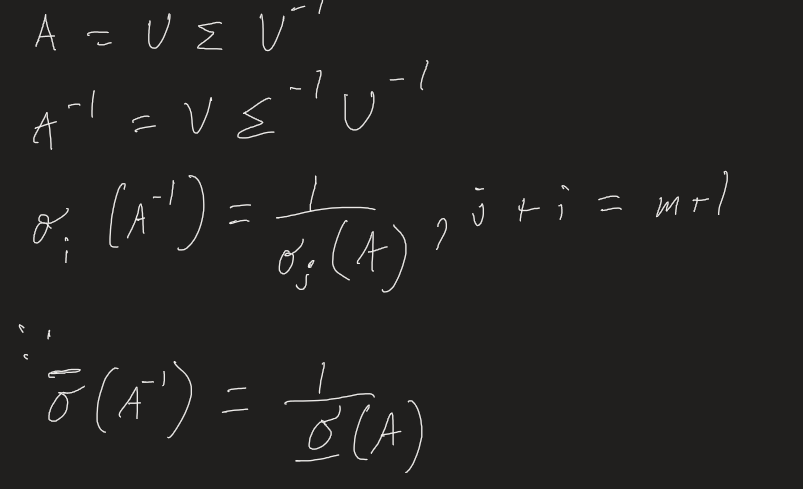

### Part c

a = sym('a', 'positive');
b = sym('b', 'positive');
epsilon = sym('epsilon', 'positive');

A = [
    -a epsilon
    0   -b
    ]

$$A = \left(\begin{array}{cc} -a & \epsilon \\ 0 & -b \end{array}\right)$$

Lambda = eig(A)

$$Lambda = \left(\begin{array}{c} -a\\ -b \end{array}\right)$$

S = svd(A)

$$S = \begin{array}{l} \left(\begin{array}{c} \sqrt{\frac{a^{2}}{2}-\sigma_{1}+\frac{b^{2}}{2}+\frac{\epsilon^{2}}{2}}\\ \sqrt{\sigma_{1}+\frac{a^{2}}{2}+\frac{b^{2}}{2}+\frac{\epsilon^{2}}{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{\left(a^{2}-2\,a\,b+b^{2}+\epsilon^{2}\right)\,\left(a^{2}+2\,a\,b+b^{2}+\epsilon^{2}\right)}}{2} \end{array}$$

sigma_lim_inf = limit(S, epsilon, inf)

$$sigma\_lim\_inf = \left(\begin{array}{c} 0\\ \infty \end{array}\right)$$

### Part d

% a = sym('a')
% A = 
B = sym('B', 2, 'real');
C = sym('C', 2, 'real');
D = sym('D', 2, 'real');

% TF
s = sym('s');
G = C \ (s * eye(2) - A) * B + D

$$G = \begin{array}{l} \left(\begin{array}{cc} D_{1,1}+\frac{B_{1,1}\,\left(C_{2,2}\,a+C_{2,2}\,s\right)}{\sigma_{1}}-\frac{B_{2,1}\,\sigma_{2}}{\sigma_{1}} & D_{1,2}+\frac{B_{1,2}\,\left(C_{2,2}\,a+C_{2,2}\,s\right)}{\sigma_{1}}-\frac{B_{2,2}\,\sigma_{2}}{\sigma_{1}}\\ D_{2,1}-\frac{B_{1,1}\,\left(C_{2,1}\,a+C_{2,1}\,s\right)}{\sigma_{1}}+\frac{B_{2,1}\,\sigma_{3}}{\sigma_{1}} & D_{2,2}-\frac{B_{1,2}\,\left(C_{2,1}\,a+C_{2,1}\,s\right)}{\sigma_{1}}+\frac{B_{2,2}\,\sigma_{3}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C_{1,1}\,C_{2,2}-C_{1,2}\,C_{2,1}\\ \sigma_{2}=C_{1,2}\,b+C_{2,2}\,\epsilon +C_{1,2}\,s\\ \sigma_{3}=C_{1,1}\,b+C_{2,1}\,\epsilon +C_{1,1}\,s \end{array}$$

% zeros(G)
% Lambda = eig(G)
% epsilonInLambda = hasSymType(Lambda,'symfunOf', epsilon)
% S = svd(G)



## Problem 4

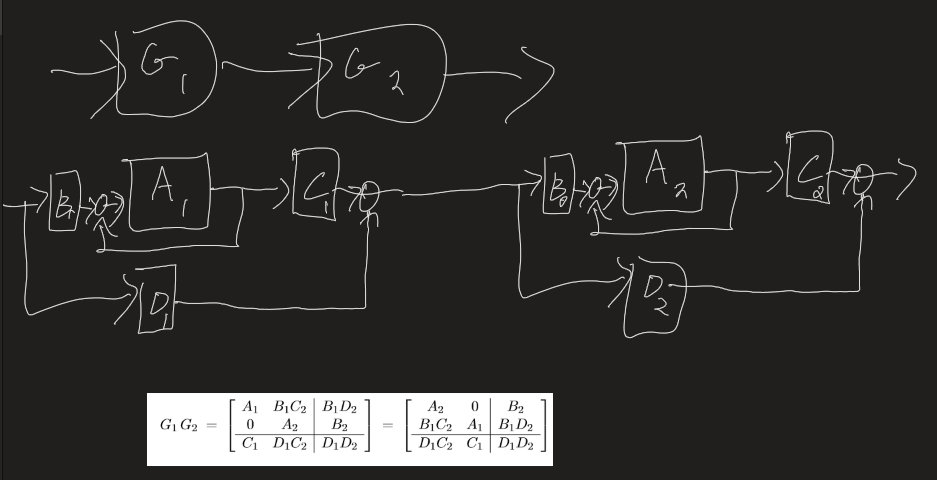

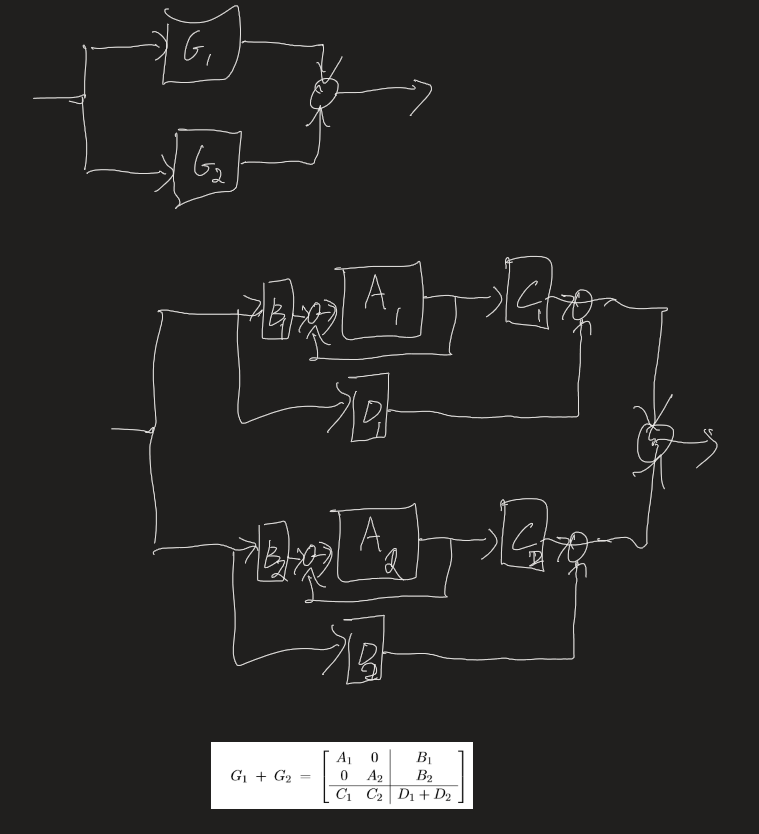

Note: Very simple... just ran out of time...

## Problem 5

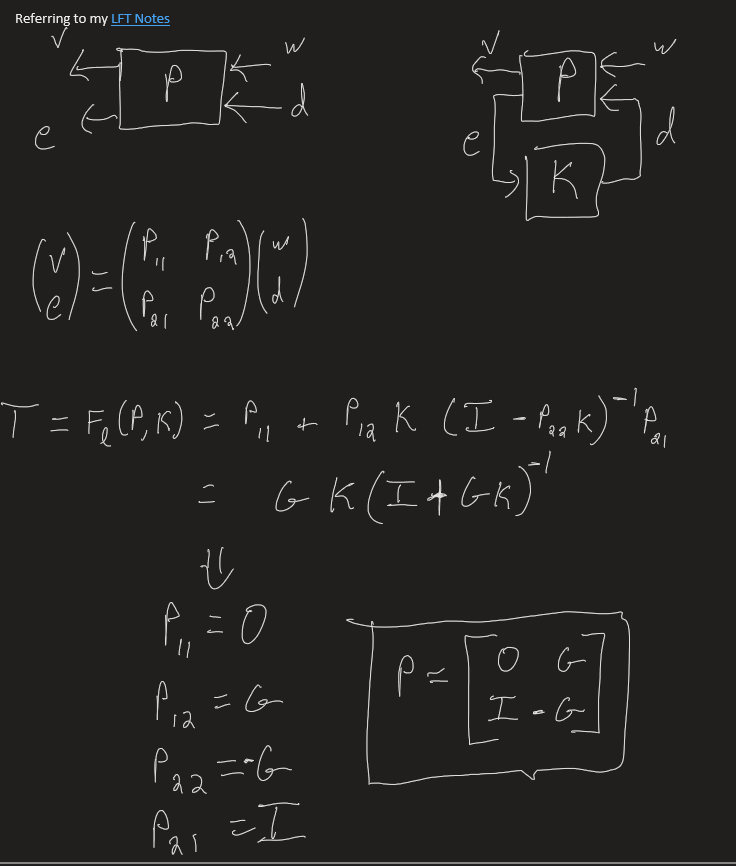

## Problem 6

Note: note great....

## Problem 7